# Práctica 7

Yimin Pan, grup 12

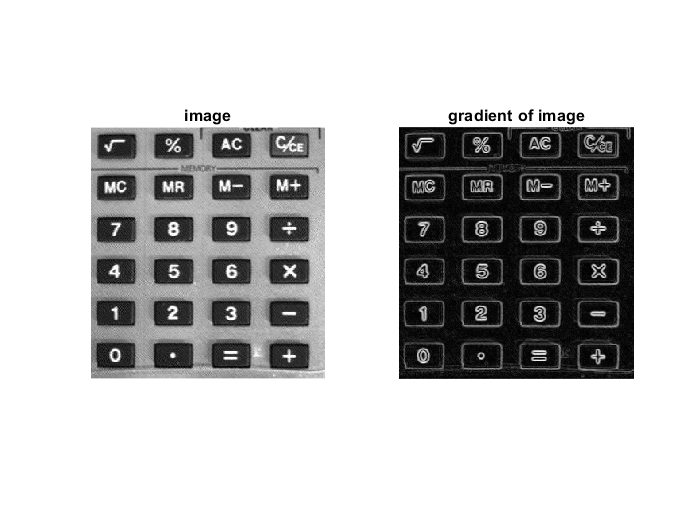

im = imread('calc.tif');
gmag = imgradient(im);
figure; 
subplot(1,2,1); imshow(im); title('image');
subplot(1,2,2); imshow(gmag, []); title('gradient of image');

## Making the foreground marker

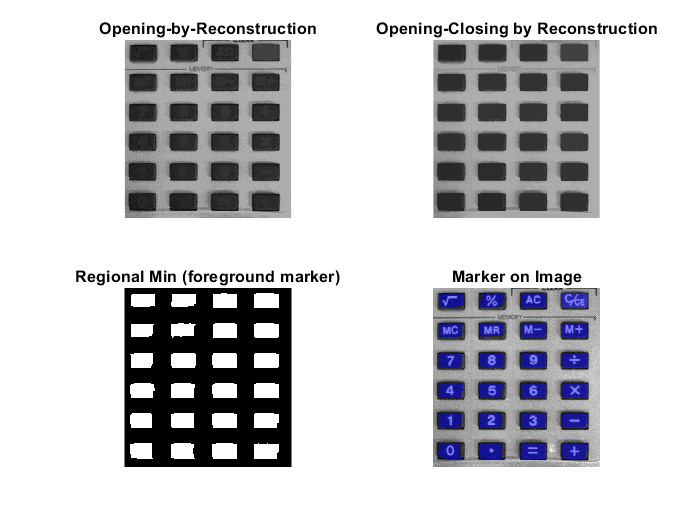

se = strel('cube', 25);
Ie = imerode(im,se);
Iobr = imreconstruct(Ie,im);
figure; subplot(2, 2 ,1); imshow(Iobr);
title('Opening-by-Reconstruction')

Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
subplot(2, 2 ,2); imshow(Iobrcbr);
title('Opening-Closing by Reconstruction')

se2 = strel(ones(5,5));
fgm = imregionalmin(Iobrcbr);
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);
fgm4 = bwareaopen(fgm3,20);
subplot(2, 2 ,3); imshow(fgm4);
title('Regional Min (foreground marker)')

I3 = labeloverlay(im,fgm4);
subplot(2, 2 ,4); imshow(I3);
title('Marker on Image')

## Making the background marker

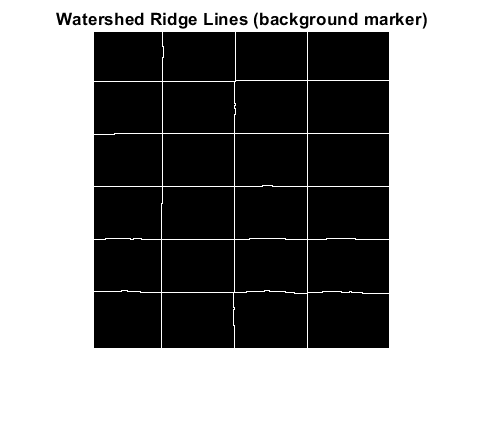

bw = imbinarize(Iobrcbr);
bw = ~bw;
D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
figure; imshow(bgm); title('Watershed Ridge Lines (background marker)');

#### Watershed with marker

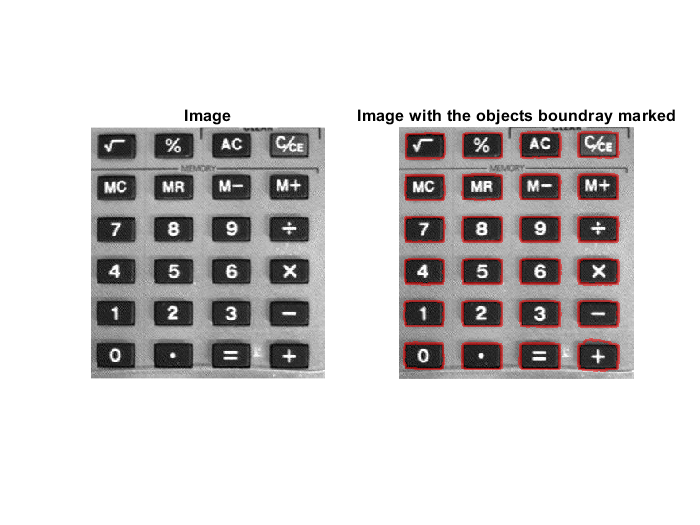

gmag2 = imimposemin(gmag, fgm|bgm);
L = watershed(gmag2);

labels = imdilate(L==0,ones(3,3));
C = [1, 0, 0];
I4 = labeloverlay(im, labels, 'Colormap', C);

figure; subplot(1,2,1); imshow(im); title('Image');
subplot(1,2,2);imshow(I4); title('Image with the objects boundray marked')